# Prognostic Health Management

**Name     **: Kwak, Jin/21900031 Kim, Sunwoo/22000090

**Date**       : 2024.10.05

**Modified**: 2024.10.28

# Introduction

In this lab, [](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)[AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM) is used to develop a machine learning model for coil defect diagnosis(Hot-Air Process Equipment)

### **Process Description**

Hot-Air Drying Process:

    - Ensures that the film and protective agents adhere stably to the metal surface after plating

    - Completely dries moisture from the product surface.

    - Used in various fields(e.g. electronic component coating, automotive paint processes, and ceramic processes)

    - **Process Defects**

        - High power consumption using coil $\rightarrow$Overheating, Irregular temperature transmission $\rightarrow$Poor product quality/Equipment Fault

        - Coil fault may cause issues with the cooling motor $\rightarrow$ Vibration patterns changes.

Simple block diagram is drawn as below

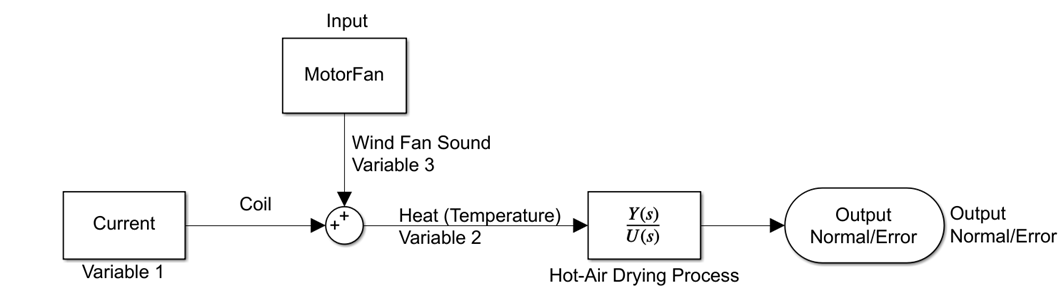

The goal is to identify these changes to diagnose the issues early on and prevent equipment failure.

## Goal of the Project

Two separate, distinguishable goals.

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish degradation model

## Specific Goals

## Strategy

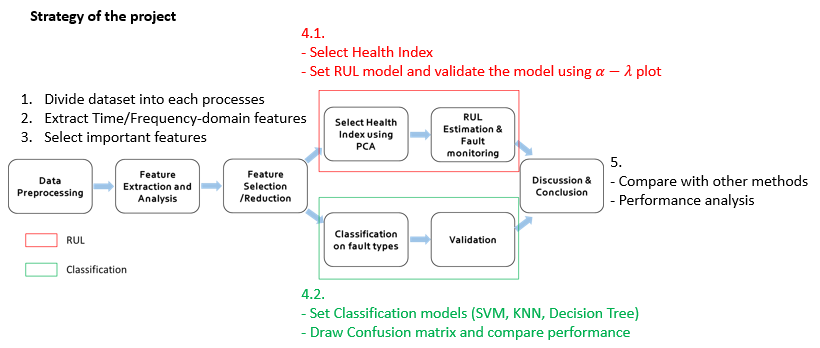

By using the sound dataset, fault can be diagnosed at the first place. This may help classify the error and provide robustness to the fault diagnosis system using machine learning.

## Dataset

Dataset name: [AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)

SCADA from: [1]KAMP

Data Measurement:

- PLC data(Sampling Period: 5[sec])

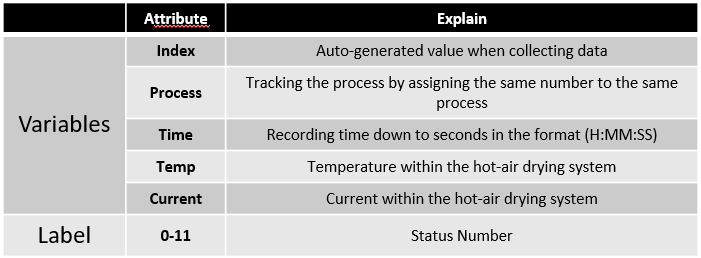

- Sound data

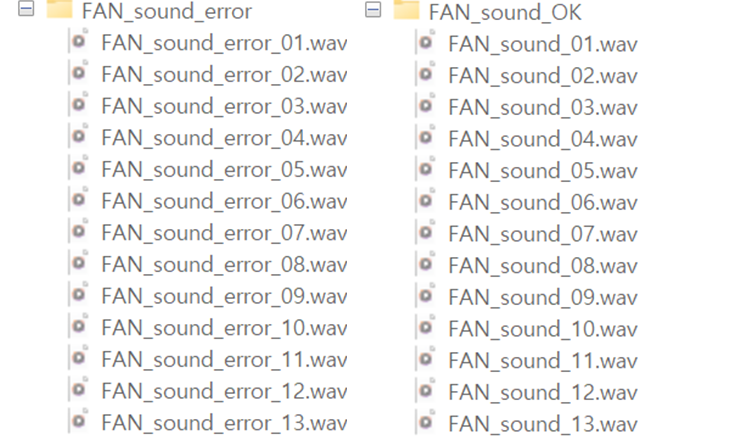

The two datasets are asynchronous. The sound data is subdivided into normal(170 files) and error(13 files).

Data Categories:

- Numerical data from PLC 

- Sound data

- Error Lot list

**Limitations on the PLC data**

- Low Sampling Frequency (0.2Hz)

- Various amount of data per process $\rightarrow$Some processes do not have enough information

- Defect frequently occurs $\rightarrow$Ambiguous to estimate RUL

**Note on this dataset:**

- Classification dataset for hot air drying process

- 12 errors are classified

## **Goal of the Project**

Two main goals of the project are introduced in this project. The dataset is originally used for classification. Authors will prepare for a **ML model for fault classification** and **Fault Diagnosis Model(Remaining Useful Life Estimation Model)**

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish **degradation model**

## **Expected Outcome**

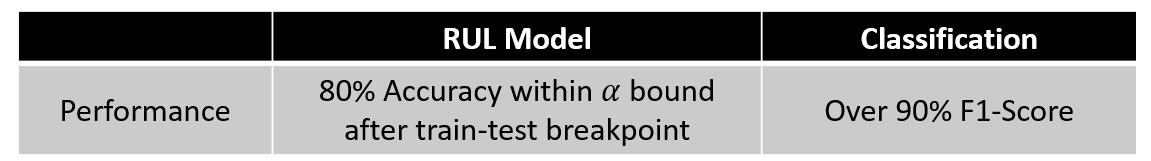

## Schedule

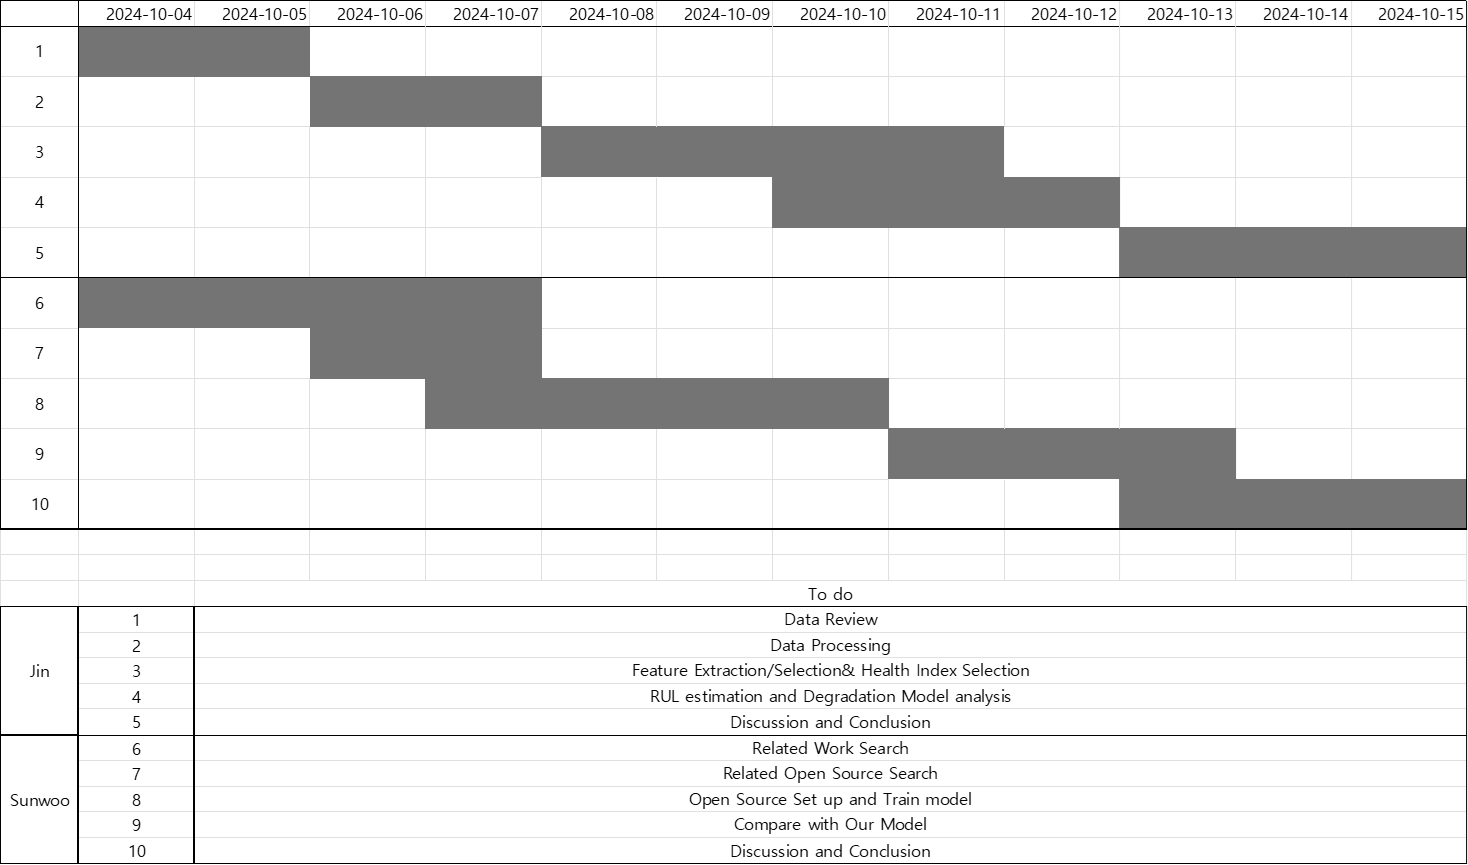

addpath("data\FAN_sound_error\");
addpath("data\FAN_sound_OK\")   ;
addpath("data\5공정_180sec\")   ;

# Data Preprocessing

**Import Sound Data **

N_sound_error = 13                               ;
N_sound_normal= 170                              ;
error_sound_filename  = "FAN_sound_error_0%d.wav";
normal_sound_filename = "FAN_sound_0%d.wav"      ;
for idx = 1:9
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end
error_sound_filename = "FAN_sound_error_%d.wav"  ;
normal_sound_filename= "FAN_sound_%d.wav"        ;
for idx = 10:13
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
end
for idx = 10:N_sound_normal
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end

**Import PLC data**

Unfortunately, the time-series data is not strictly real-time, in which means that this data is collected every 5 seconds **approximately**.

Most frequency features are excluded as the real-time collection of data is not achieved.

day   = [6:10,13:17,23,24,27:30,1,5:8,12:15,18:22,25:27];
month = [9*ones(1,16),10*ones(1,17)];
dates = datetime(2021,month,day,'Format','uuuu.MM.dd');
txt_form = "kemp-abh-sensor-%s.csv";
for idx = 1:length(day)
    file_name    = sprintf(txt_form,dates(idx));
    data_temp    = readmatrix(file_name) ; 
    plc_data{idx}= data_temp(:,[1,2,4,5]); 
end

**Data Enumeration**

Cell data will be in time-series and each features are grouped by a struct.

% Enumerations
TIME_STEP= 1  ;PROCESS  = 2  ;TEMP     = 3  ;CURRENT  = 4  ;CLASS    = 5  ;
% For cell data
RAW_DATA = 1  ;MAX_FREQ = 2  ;FEAT     = 3  ;

BREAK_POINT = 2;
N_process   = 43;

# Sound Feature Extraction

**The sound data** is very similar to the vibration data as it has amplitude and frequency. Time and frequency features[2] are to be extracted for the data analysis. The features extracted are the following:

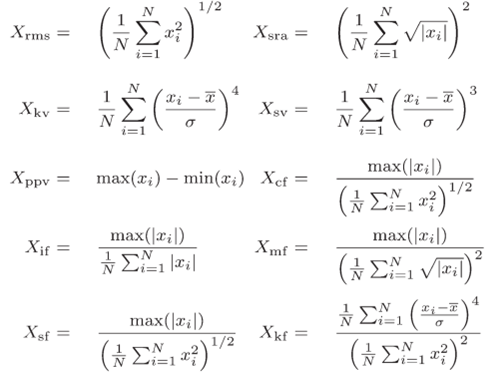

However, the sound data is subdivided into normal/error and is not time-series at all, which means this should be only used as classification not RUL. Only possible if the sound data can be collected on real-time.

for idx = 1 : N_sound_error
    sound_error{idx,3} = get_features_sound(sound_error{idx,1});
end
for idx = 1 : N_sound_normal
    sound_normal{idx,3} = get_features_sound(sound_normal{idx,1});
end

Compare time-domain sound data of normal/error. 

Random sample is chosen.

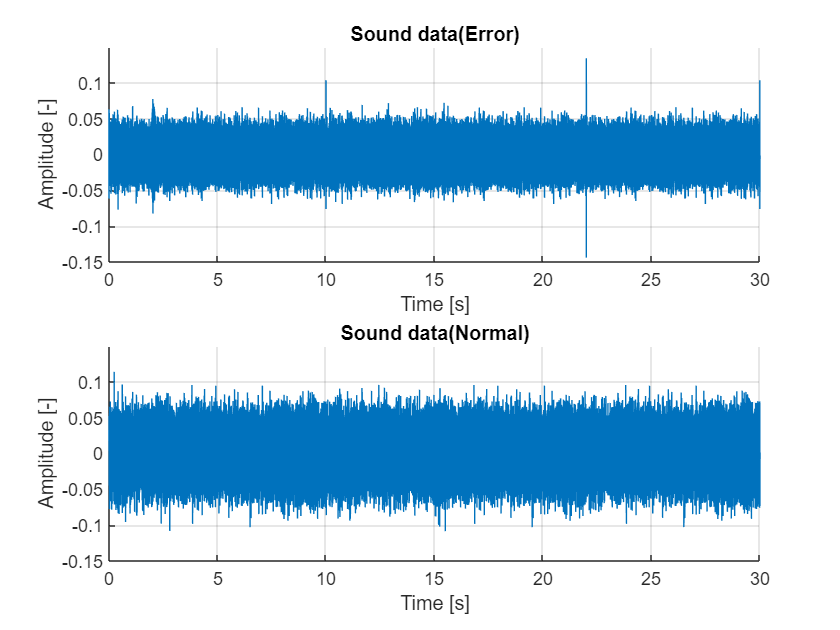

rng(0);
idx = randi(13);
Fs  = 44100;
ex_sound_error = sound_error {idx,RAW_DATA}(:,1);
ex_sound_normal= sound_normal{idx,RAW_DATA}(:,1);
time = 0:1/Fs:(length(ex_sound_error)-1)/Fs;

figure;
subplot(2,1,1); hold on;
title('Sound data(Error)','FontWeight','bold');
plot(time, ex_sound_error);grid on;
xlabel('Time [s]'); ylabel("Amplitude [-]");
time = 0:1/sound_normal{idx,MAX_FREQ}:(length(ex_sound_normal)-1)/Fs;
ylim([-0.15 0.15]);
subplot(2,1,2); hold on;
title('Sound data(Normal)','FontWeight','bold');
plot(time, ex_sound_normal); grid on;
xlabel('Time [s]'); ylabel("Amplitude [-]");
ylim([-0.15 0.15]);

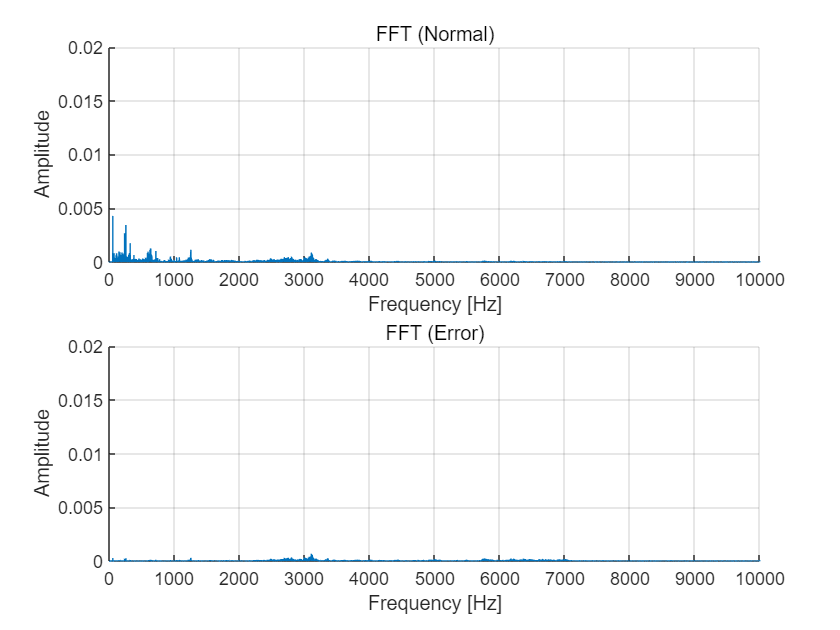

Fs = 44100;  %Hz
figure;
[freq, amp_normal] = get_fft(ex_sound_normal,Fs);
[freq, amp_error]  = get_fft(ex_sound_error,Fs);
figure; 
subplot(2,1,1); hold on; grid on;
plot(freq,amp_normal); xlabel('Frequency [Hz]'); ylabel('Amplitude');
title('FFT (Normal)');ylim([0 0.02]); xlim([0 1e4]);
subplot(2,1,2); hold on; grid on;
plot(freq,amp_error); xlabel('Frequency [Hz]'); ylabel('Amplitude'); 
title('FFT (Error)');ylim([0 0.02]); xlim([0 1e4]);

To further illustrate the frequency features of normal/error data, `get_freq_features()` function is used.

normal_frequency_features = get_freq_features(amp_normal,Fs)

normal_frequency_features = 1×3 table
    max_amplitude    frequency_of_max_amplitude     DC_value 
    _____________    __________________________    __________

      0.0042892                117.27              4.4962e-06


error_frequency_features  = get_freq_features(amp_error,Fs)

error_frequency_features = 1×3 table
    max_amplitude    frequency_of_max_amplitude     DC_value 
    _____________    __________________________    __________

     0.00071702                36206               2.7475e-07


To classify Normal/Error, logistic regression model is used.

Reason for the model is that logistic regression is suitable for binary classifiction and is done by probability calculation using a logistic function.

% Train/Test Split
sound_dataset_train = table;
sound_dataset_test  = table;
N_sound_error = length(sound_error);
N_sound_normal= length(sound_normal);
rng(0);
cv_error = cvpartition(N_sound_error, 'Holdout' , 0.2);
cv_normal= cvpartition(N_sound_normal, 'Holdout', 0.2);
test_error_idx = cv_error.test;
test_normal_idx= cv_normal.test;
test_cnt = 1;
train_cnt= 1;
for idx = 1:N_sound_error
    if(test_error_idx(idx))
        sound_dataset_test(test_cnt,1:14) = struct2table(sound_error{idx,3},'AsArray',true);
        sound_dataset_test(test_cnt,15)   = cellstr("Error");
        test_cnt = test_cnt + 1;
        
    else
        sound_dataset_train(train_cnt,1:14) = struct2table(sound_error{idx,3},'AsArray',true);
        sound_dataset_train(train_cnt,15)   = cellstr("Error");
        train_cnt = train_cnt + 1;
    end
end

idx_error = 1;
for idx = 1:N_sound_normal
    if(test_normal_idx(idx))
        sound_dataset_test(test_cnt,1:14) = struct2table(sound_normal{idx,3},'AsArray',true);
        sound_dataset_test(test_cnt,15)   = cellstr("Normal");
        test_cnt = test_cnt + 1;
    else
        sound_dataset_train(train_cnt,1:14) = struct2table(sound_normal{idx,3},'AsArray',true);
        sound_dataset_train(train_cnt,15)   = cellstr("Normal");

        train_cnt = train_cnt + 1;
        idx_error = idx_error + 1;
        if idx_error>N_sound_error*2
            break;
        end
    end
end

Xtrain =sound_dataset_train(:,1:14);
Ytrain =sound_dataset_train(:,15);

X = table2array(Xtrain);
Y = categorical(table2cell(Ytrain));
Xtest = table2array(sound_dataset_test(:,1:14));
Ytest = categorical(table2cell(sound_dataset_test(:,15)));

rng(0);
LogisticRegressionModel =  fitclinear(X,Y,'Learner','logistic', 'KFold',5)

LogisticRegressionModel =   ClassificationPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Y'
        NumObservations: 37
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [Error    Normal]
         ScoreTransform: 'none'


  Properties, Methods


kfoldloss  = kfoldLoss(LogisticRegressionModel)

kfoldloss = 0.2973

Xtest_1   = Xtest;
loss_test = loss(LogisticRegressionModel.Trained{1},Xtest_1,Ytest)

loss_test = 0.2973

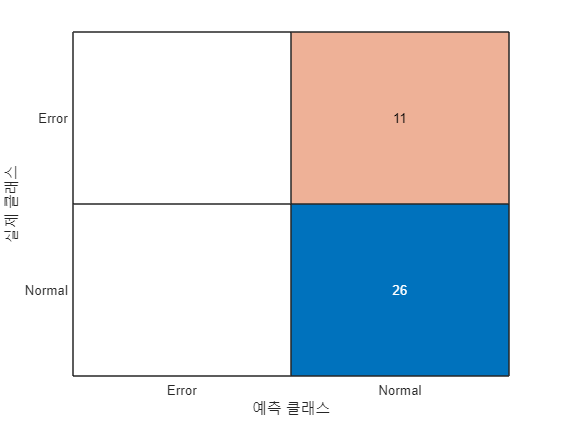

predictClass = predict(LogisticRegressionModel.Trained{1}, X);
figure; conf_mat = confusionchart(Y, predictClass);

Each time features, frequency features are collected and averaged. They are plotted as below.

First few sample data time features plot. This shows that error sound is very random and shows inconsistent values of all features.

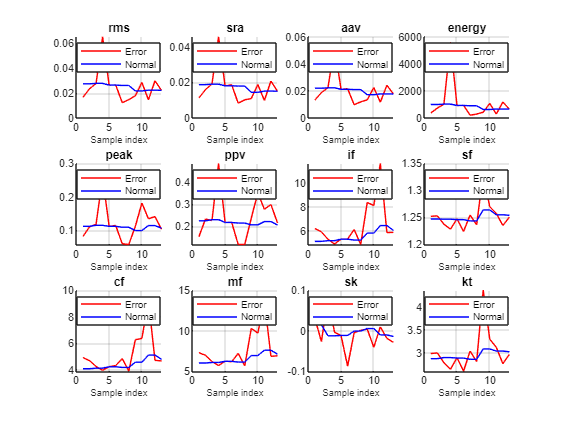

feature_names =["rms" "sra" "aav" "energy" "peak" "ppv" "if" "sf" "cf" "mf" "sk" "kt" "fft"];
figure;
for idx = 1:(length(feature_names)-1)
    avg(idx,1) = get_average_feature(sound_error ,feature_names(idx))       ;
    avg(idx,2) = get_average_feature(sound_normal,feature_names(idx))       ;
    error_features(:,idx)= get_all_feature(sound_error ,feature_names(idx)) ;
    normal_features(:,idx)= get_all_feature(sound_normal,feature_names(idx));
    subplot(3,4,idx); hold on; grid on           ;
    plot(error_features(:,idx),'r-')             ; 
    plot(normal_features(1:13,idx),'b-')         ;
    legend('Error','Normal')                     ;
    legend('Location','best')                    ;
    xlabel('Sample index','FontSize',7)          ;
    title(feature_names(idx),'FontWeight','bold');
end

# PLC data Preprocessing/Feature Extraction

Feature extraction for PLC dataset is same as RUL dataset. Mostly, time domain features are extracted.

For classification, another output(label) is added in the feature extraction.

% PLC time-domain analysis
N_plc = 33;
Fs = 1.0 /5.0;
for idx = 1 : N_plc
    temp = plc_data {idx};
    plc_current{idx,1}  = temp(:,3);
    plc_current{idx,2}  = Fs;
    plc_current{idx,3}  = get_features(plc_current{idx,1});
    plc_temperature{idx,1}= temp(:,4);
    plc_temperature{idx,2}= Fs;
    plc_temperature{idx,3}= get_features(plc_temperature{idx,1});
end

error_list = readmatrix("Error Lot list.csv");
error_list = error_list(2:end,2:end);
if exist("var_names")
    clear var_names;
end
if exist("var_types")
    clear var_types;
end

for idx =1:length(error_list(1,:))
    var_names(idx) = sprintf("Error%d",idx);
end
var_names  = ["datetime" var_names];
error_names= var_names(2:end);

var_types(1,1:11) = "double";

var_types = ["datetime" var_types];
size_error_list =size(error_list);
size_error_list(2) = size_error_list(2)+1;
error_table= table('Size',size_error_list,'VariableTypes',var_types,'VariableNames',var_names);
error_table.datetime = dates';
for row = 1:length(error_list(:,1))
    for col = 1:length(error_list(1,:))
        if isnan(error_list(row,col))
            error_list(row,col) = 0;
        end
    end
end
error_table(:,2:end) = array2table(error_list);
% Sort by error
for row = 1:length(plc_data)
    temp_plc_data      = plc_data{row};
    temp_plc_data(:,5) = 0;
    for col= 1:length(error_list(1,:))
        if error_list(row,col) ~= 0
            indices = find(temp_plc_data(:,2) == error_list(row,col));
            temp_plc_data(indices,5) = col;
        end
    end
    plc_data{row} = temp_plc_data;
end

# Feature Extraction For Classification

Split into train data and test data

rng(0);
cv = cvpartition(length(day), 'Holdout', 0.2);
test_idx = cv.test;
test_idx(16,1) = 0;
cnt_test = 1;
cnt_train= 1;
% Each cell is test/train dataset.
% Each column represents number of process, current or temperature, and
% classification respectively
for idx = 1:length(day)
        PLC_current{idx}                = plc_data{idx}(:,[PROCESS CURRENT CLASS]);
        PLC_temperature{idx}            = plc_data{idx}(:,[PROCESS TEMP CLASS]);
    if test_idx(idx)
        test_current{cnt_test}     = plc_data{idx}(:,[PROCESS CURRENT CLASS]);
        test_temperature{cnt_test} = plc_data{idx}(:,[PROCESS TEMP CLASS]);
        cnt_test = cnt_test + 1;
    else
        train_current{cnt_train}     = plc_data{idx}(:,[PROCESS CURRENT CLASS]);
        train_temperature{cnt_train} = plc_data{idx}(:,[PROCESS TEMP CLASS]);
        cnt_train= cnt_train + 1;
    end
end

for idx_day = 1:length(PLC_current)
    PLC_current_day = PLC_current{idx_day};
    PLC_temperature_day = PLC_temperature{idx_day};
    process = 1;
    start_idx = 1;
    for idx_time = 1:length(PLC_current_day)
        if PLC_current_day(idx_time,1) ~= process  
            end_idx = idx_time - 1;
            idx_feature = process + (43 * (idx_day - 1));
            PLC_feature(idx_feature) = get_features_plc(PLC_temperature_day(start_idx:end_idx,2), PLC_current_day(start_idx:end_idx,2), PLC_current_day(start_idx:end_idx,3)) ;
            process = PLC_current_day(idx_time,1);
            start_idx = idx_time ;
        end
        if PLC_current_day(idx_time,1) == 43
            end_idx = length(PLC_current_day);
            idx_feature = process + (43 * (idx_day - 1));
            PLC_feature(idx_feature) = get_features_plc(PLC_temperature_day(start_idx:end_idx,2), PLC_current_day(start_idx:end_idx,2), PLC_current_day(start_idx:end_idx,3)) ;
        end 
    end
end
for idx_day = 1:length(train_current)
    train_current_day = train_current{idx_day};
    train_temperature_day = train_temperature{idx_day};
    process = 1;
    start_idx = 1;
    for idx_time = 1:length(train_current_day)
        if train_current_day(idx_time,1) ~= process  
            end_idx = idx_time - 1;
            idx_feature = process + (43 * (idx_day - 1));
            train_feature(idx_feature) = get_features_plc(train_temperature_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,3)) ;
            process = train_current_day(idx_time,1);
            start_idx = idx_time ;
        end
        if train_current_day(idx_time,1) == 43
            end_idx = length(train_current_day);
            idx_feature = process + (43 * (idx_day - 1));
            train_feature(idx_feature) = get_features_plc(train_temperature_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,3)) ;
        end 
    end
end

for idx_day = 1:length(test_current)
    test_current_day = test_current{idx_day};
    test_temperature_day = test_temperature{idx_day};
    process = 1;
    start_idx = 1;
    
    for idx_time = 1:length(test_current_day)
        if test_current_day(idx_time,1) ~= process  
            end_idx = idx_time - 1;
            idx_feature = process + (43 * (idx_day - 1));
            test_feature(idx_feature) = get_features_plc( test_temperature_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,3)) ;          
            process = test_current_day(idx_time,1);
            start_idx = idx_time ;
        end
        if test_current_day(idx_time,1) == 43
            end_idx = length(test_current_day);
            idx_feature = process + (43 * (idx_day - 1));
            test_feature(idx_feature) = get_features_plc( test_temperature_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,3)) ;
        end
    end
end

Then features are selected

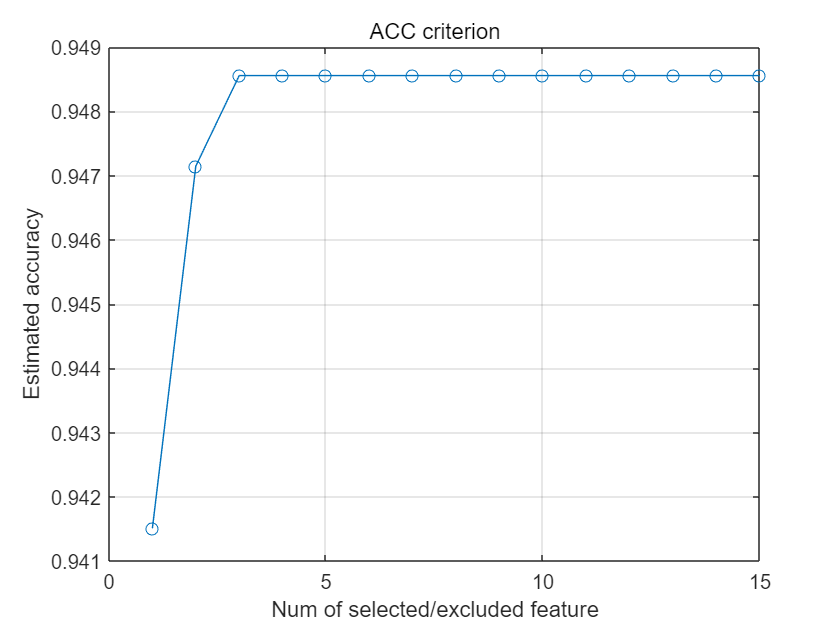

filed = struct2table(train_feature);
train_data = table2array(filed(:,1:28));
error = table2array(filed(:,"error"));

PLC_data_2 = struct2table(PLC_feature) ;
PLC_data = table2array(PLC_data_2(:,1:28)) ;
Y = table2array(PLC_data_2(:,29)) ;

if exist("X")
    clear X
end
N_feature = 28;
N_select  = 15;
idx_min   = 1;
errorRate_min = ones(1,N_select);
select_mat = zeros(1,N_feature);

for idx_1 = 1:N_select
    for idx_2 = 1:N_feature
        if select_mat(idx_2)
            continue;
        end
        X(:,idx_1) = PLC_data(:,idx_2);
        mdl  = fitcecoc( X , Y );
        errorRate = loss(mdl, X, Y, 'LossFun', 'classiferror');
        if errorRate < errorRate_min(idx_1)
            errorRate_min(idx_1) = errorRate ;
            idx_min = idx_2 ;
        end
    end
    select_mat(idx_min) = 1;
    X(:,idx_1) = PLC_data(:,idx_min);
end
est_accuracy = 1-errorRate_min;

figure
plot(est_accuracy, '-o'); title("ACC criterion");   grid on;
xlabel("Num of selected/excluded feature"); ylabel("Estimated accuracy");

select = table2array(struct2table(load("select.mat")));

# Classification

## SVM

% Classification using SVM
classLabels = categorical([0 , 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11]);
X_mdl = PLC_data(:,select==1);

SVM= fitcecoc(X_mdl, Y, 'Learners', templateSVM('KernelFunction', 'rbf'), ...
              'ClassNames', classLabels, 'Coding', 'onevsall', 'Verbose', 1)

111개의 음성 관측값과 1308개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 1(SVM)을(를) 훈련시키는 중입니다.
1396개의 음성 관측값과 23개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 2(SVM)을(를) 훈련시키는 중입니다.
1396개의 음성 관측값과 23개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 3(SVM)을(를) 훈련시키는 중입니다.
1398개의 음성 관측값과 21개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 4(SVM)을(를) 훈련시키는 중입니다.
1406개의 음성 관측값과 13개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 5(SVM)을(를) 훈련시키는 중입니다.
1407개의 음성 관측값과 12개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 6(SVM)을(를) 훈련시키는 중입니다.
1410개의 음성 관측값과 9개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 7(SVM)을(를) 훈련시키는 중입니다.
1416개의 음성 관측값과 3개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 8(SVM)을(를) 훈련시키는 중입니다.
1416개의 음성 관측값과 3개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 9(SVM)을(를) 훈련시키는 중입니다.
1417개의 음성 관측값과 2개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 10(SVM)을(를) 훈련시키는 중입니다.
1418개의 음성 관측값과 1개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 11(SVM)을(를) 훈련시키는 중입니다.
1418개의 음성 관측값과 1개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 12(SVM)을(를) 훈련시키는 중입니다.


SVM =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1    2    3    4    5    6    7    8    9    10    11]
           ScoreTransform: 'none'
           BinaryLearners: {12×1 cell}
               CodingName: 'onevsall'


  Properties, Methods


Dimension is chosen as 3. The reason for this hyperparameter is to reduce dimension(which may be more prone to overfit) while accuracy is high.

ErrorRate = loss(SVM, X_mdl, Y, 'LossFun', 'classiferror');
accuracy = 1-ErrorRate

accuracy = 0.9972

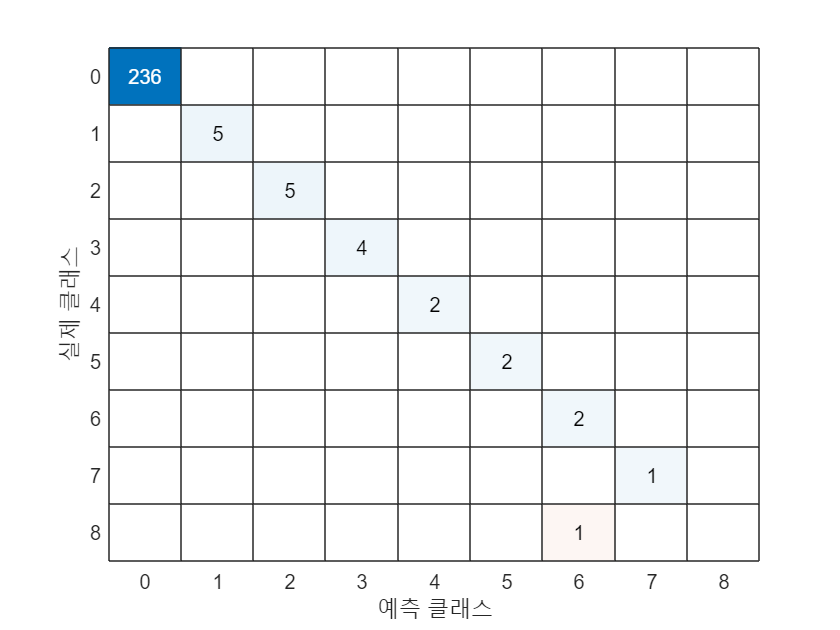

Xtest_2 = struct2table(test_feature);
Xtest_1 = table2array(Xtest_2);
Xtest   = Xtest_1(:,select == 1);
Ytest = Xtest_1(:,29);
mlClass = predict(SVM,Xtest);
mlClass_double = double(string(mlClass));
figure;
SVM_conf_mat = confusionchart(Ytest,mlClass_double);

## KNN

The reason for the hyperparameter: 

K is selected using quantitative approach. Some labels only occurred once/twice so they could not be trained/tested well. For the same reason, the concept of neighbor could never be used in KNN. Therefore, hyperparameter K is carefully chosen by experiment.

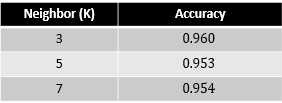

KNN = fitcknn(X_mdl, Y, "NumNeighbors", 2)

KNN =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9 10 11]
           ScoreTransform: 'none'
          NumObservations: 1419
                 Distance: 'euclidean'
             NumNeighbors: 2


  Properties, Methods


ErrorRate = loss(KNN, X_mdl, Y, 'LossFun', 'classiferror');
accuracy = 1-ErrorRate

accuracy = 0.9662

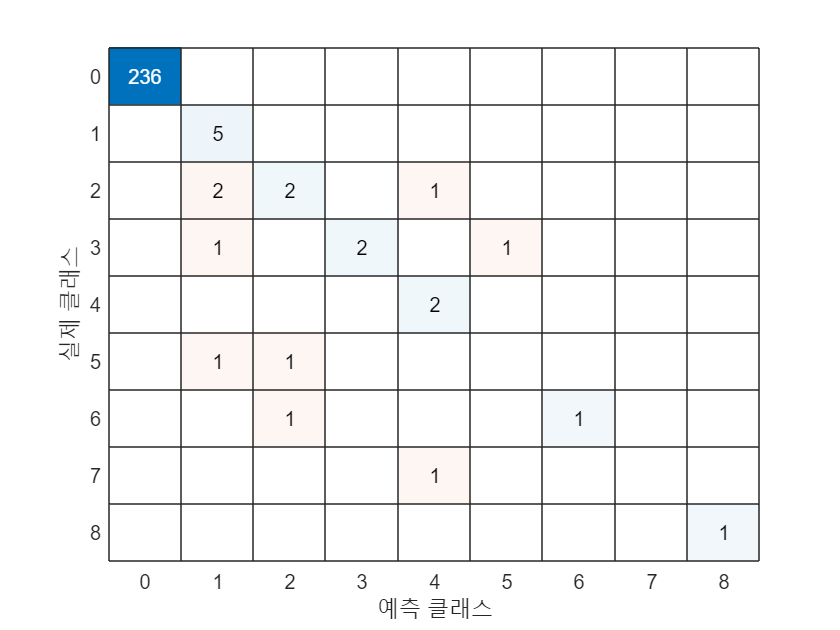

mlClass = predict(KNN,Xtest);
mlClass_double = double(string(mlClass));
figure
KNN_conf_mat= confusionchart(Ytest,mlClass_double);

## Tree

mdl_tree = fitctree(X_mdl , Y)

mdl_tree =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9 10 11]
           ScoreTransform: 'none'
          NumObservations: 1419


  Properties, Methods


ErrorRate = loss(mdl_tree, X_mdl, Y, 'LossFun', 'classiferror');
accuracy = 1-ErrorRate

accuracy = 0.9697

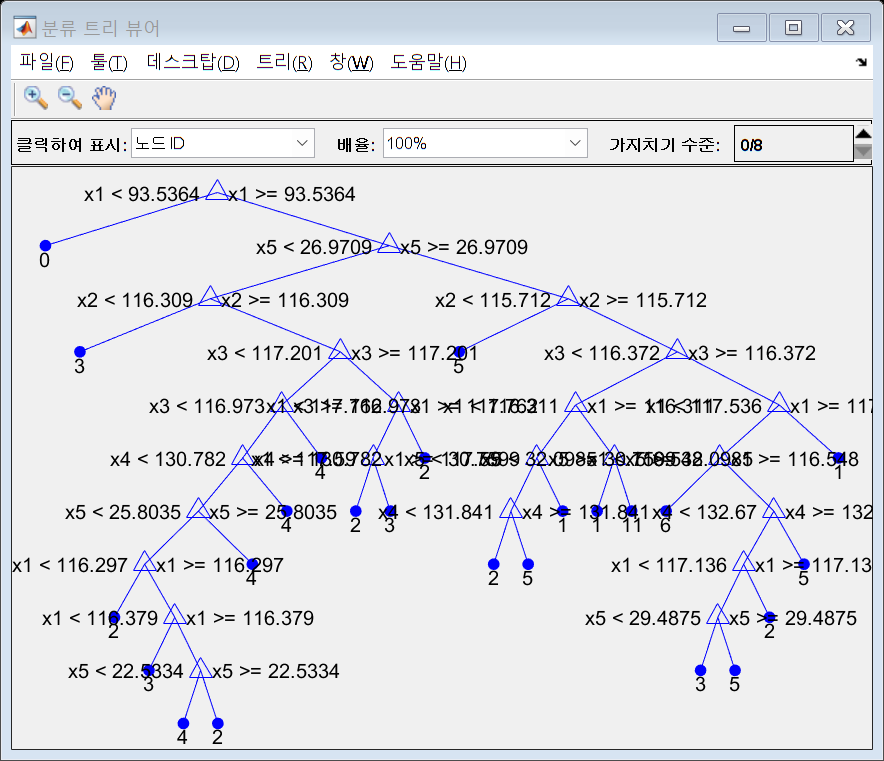

view(mdl_tree,'Mode','graph');

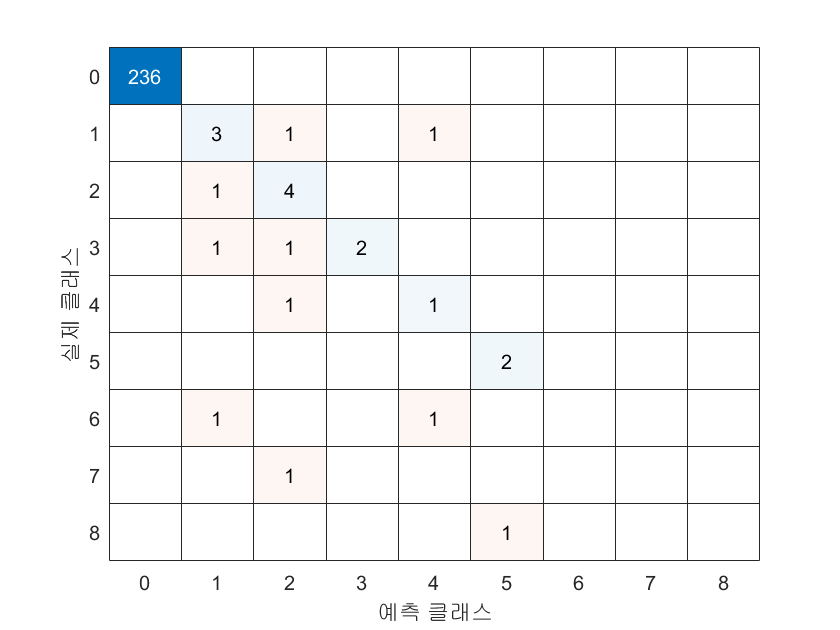

mlClass = predict(mdl_tree,Xtest);
mlClass_double = double(string(mlClass));
figure
tree_conf_mat = confusionchart(Ytest,mlClass_double);

N_tree = 20;
Mdl_rf = TreeBagger(N_tree,X_mdl,Y, Method="classification", OOBPrediction="on")

Mdl_rf =   TreeBagger
20개 배깅 결정 트리를 사용한 앙상블:
                    Training X:             [1419x5]
                    Training Y:             [1419x1]
                        Method:       classification
                 NumPredictors:                    5
         NumPredictorsToSample:                    3
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '0'             '1'            '10'            '11'             '2'             '3'             '4'             '5'             '6'             '7'             '8'             '9'

  Properties, Met

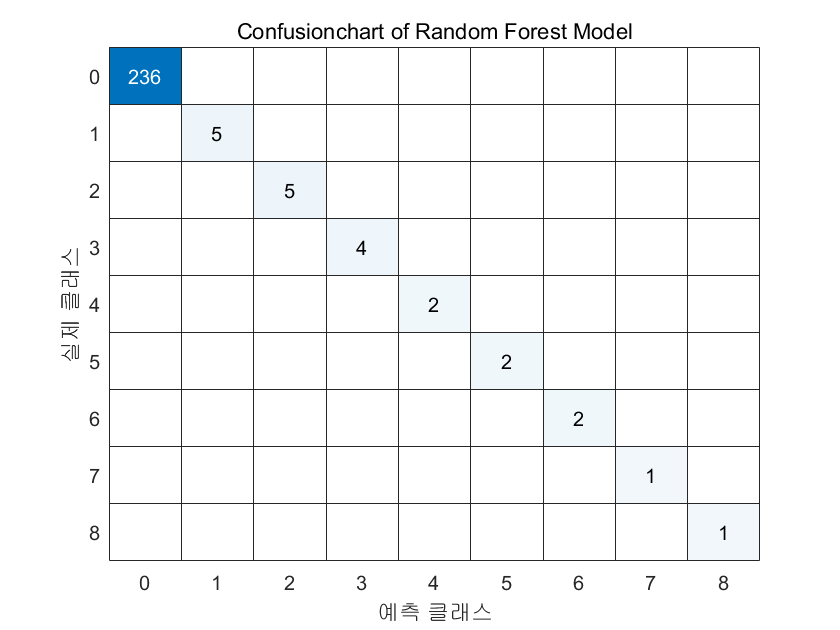

mlClass = predict(Mdl_rf,Xtest);
mlClass_double = double(string(mlClass));
figure
ldaResubCM = confusionchart(Ytest,mlClass_double);
title("Confusionchart of Random Forest Model")

 After all, Random Forest model showed the best performance among 4 Machine Learning Classification models.

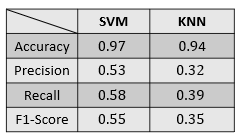

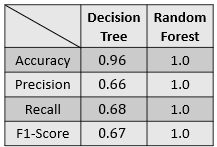

# Feature Extraction For RUL estimation

% Sort for RUL model.
KT    = 1 ;MEAN  = 2 ;STD   = 3 ;RMS   = 4 ;SRA   = 5 ;AAV   = 6 ;ENERGY= 7 ;
PEAK  = 8 ;P2P   = 9 ;IF    = 10;SF    = 11;CF    = 12;MF    = 13;SK    = 14;
names_of_feature = ["Kurtosis" "Mean" "Standard Deviation" "Root Mean Squared" "SRA" "AAV" "Energy" "Peak" "Peak to Peak" "IF" "SF" "CF" "MF" "Skewness"];
cnt = 1;
for row = 1:length(plc_data)
    % There are PLC dataset where there is no error
    % To prevent this, some dataset are not taken as a RUL dataset
    if(max(error_list(row,:)) == 0)
        continue;
    end
    temp_plc_data  = plc_data{row};
    indices = (find(error_list(row,:)>0));  % Find indices of error processes
    min_index   =min(error_list(row,indices));
    min_idx =min(find(temp_plc_data(:,2) == min_index));
    
    max_index   =max(error_list(row,indices));  % Process number
    max_idx =max(find(temp_plc_data(:,2) == max_index));
    temp_plc_data = temp_plc_data(1:max_idx,:);
    
    RUL_data{cnt,1} = temp_plc_data;            % PLC dataset with fault in it
    RUL_data{cnt,2} = [min_idx, max_idx, min_index, max_index];       % Break-point

    feature_temp   =[];
    feature_curr   =[];
    for num = 1:max_index
        indices = find(temp_plc_data(:,PROCESS) == num);
        tem_features = get_features(temp_plc_data(indices,TEMP));
        cur_features = get_features(temp_plc_data(indices,CURRENT));
        feature_temp   = [feature_temp; tem_features.kt  tem_features.mean  tem_features.std   tem_features.rms   tem_features.sra   tem_features.aav   tem_features.energy tem_features.peak  tem_features.ppv   tem_features.if    tem_features.sf    tem_features.cf    tem_features.mf    tem_features.sk];      
        feature_curr   = [feature_curr; cur_features.kt    cur_features.mean  cur_features.std   cur_features.rms   cur_features.sra   cur_features.aav   cur_features.energy cur_features.peak  cur_features.ppv   cur_features.if    cur_features.sf    cur_features.cf    cur_features.mf    cur_features.sk];
    end
    RUL_data{cnt,TEMP}  = feature_temp;
    RUL_data{cnt,CURRENT}=feature_curr;
    cnt = cnt + 1;
end

There are 23 RUL dataset. Each dataset starts from the first process until (failure)error.

# Feature Reduction for RUL

Features of RUL dataset are extracted by each process $\rightarrow$ 5 process features are plotted as below. 

As each dataset may show different aspects, each data should be shown and global pool should be reduced in multi-faceted manner.

Through essential features may be included in the set while other features will be reduced to prevent curse of dimensionality and computational burden.

The table below shows the error number and the corresponding process where the error occured. There are many errors within a day and this means it is very difficult to decide when is the end of RUL. However in the table, the errors occur consecutively and the authors decided to pick the break start point at the start of the degradation.

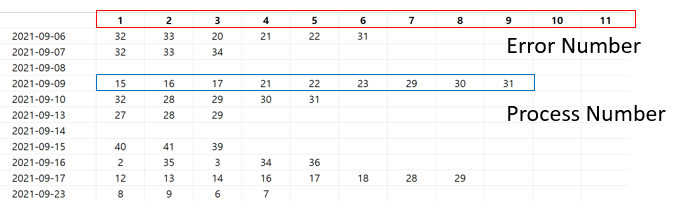

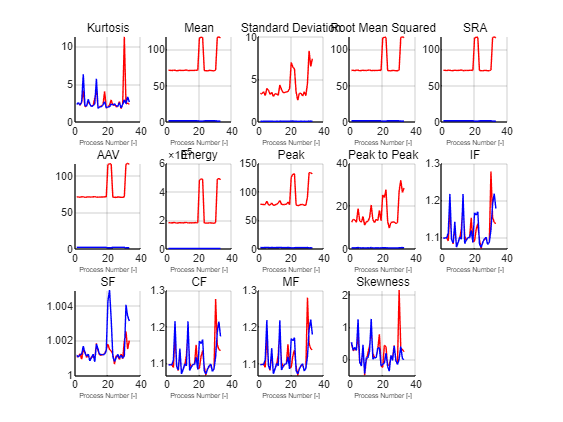

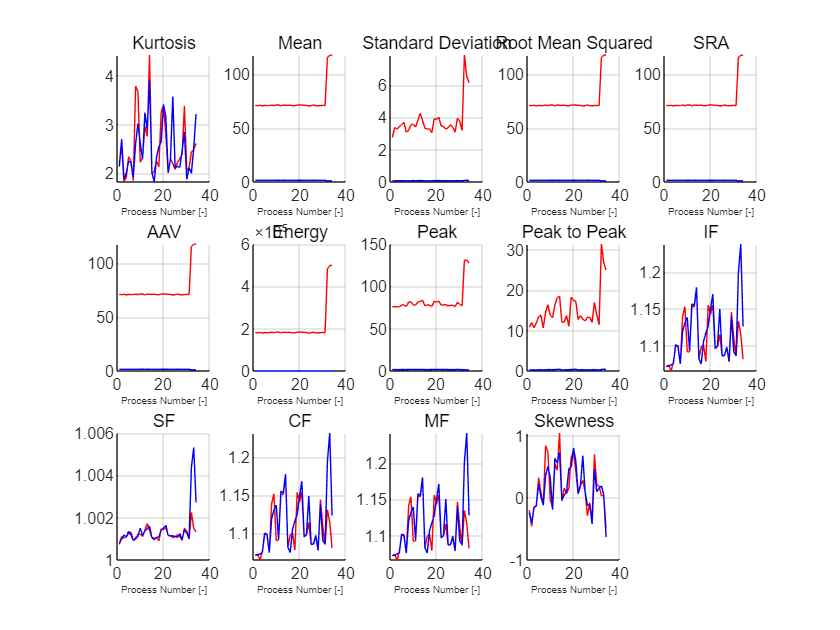

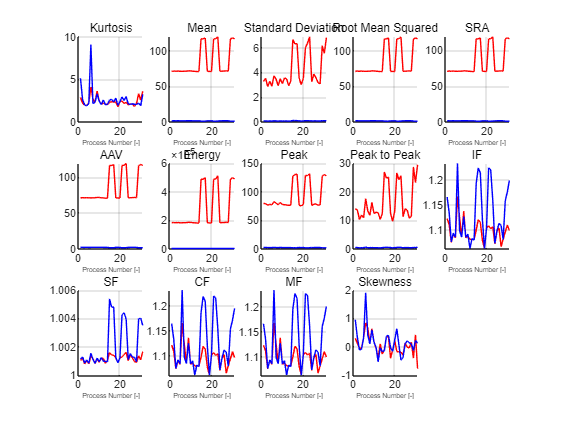

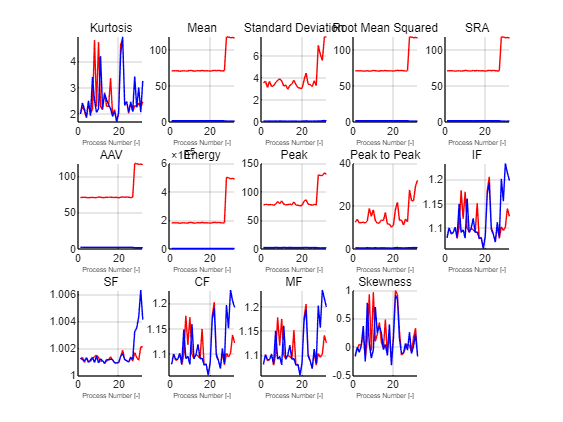

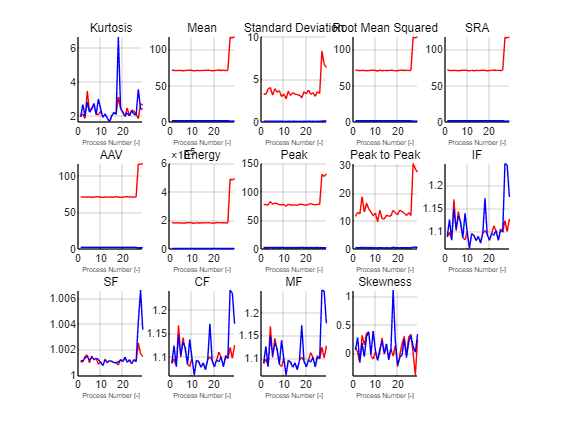

for idx = 1:5
    figure;
    temp_temp = RUL_data{idx,TEMP};
    temp_curr = RUL_data{idx,CURRENT};
    N = 1:length(temp_curr(:,1));
    for features = 1:14
        subplot(3,5,features);
        hold on; grid on;
        title(names_of_feature(features));
        plot(N,temp_temp(:,features),'r-')    ;
        plot(N,temp_curr(:,features),'b-')    ;
        xlabel('Process Number [-]','FontSize',5) ;
    end
    
end

As the every dataset is preprocessed until the error point, the dataset is tabulated. 

Rows     : Process

Columns: Features (First 14 columns: temp features, next 14 columns: current features)

rng(0);
idx = randi(23);
% Concatenate features (Temperature and Current)
features_in_array = [RUL_data{idx,TEMP} RUL_data{idx,CURRENT}];
features_in_table = array2table(features_in_array);
features_in_table.Properties.VariableNames = [strcat("temp",names_of_feature) strcat("current",names_of_feature)];

As there is small number of processes in the dataset, window size of moving average filter is relatively small(<=3) and the time delay is relatively small.

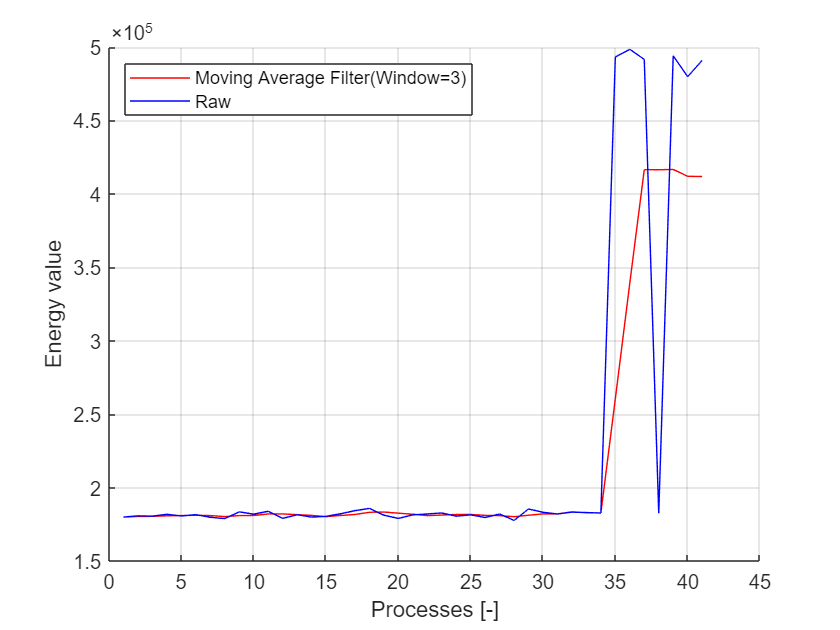

window_size = 3;
features_in_table_MAF5 = varfun(@(x) movmean(x, [window_size 0]), features_in_table);
features_in_table_MAF5.Properties.VariableNames = features_in_table.Properties.VariableNames;
figure; hold on; grid on;
xlabel('Processes [-]'); ylabel('Energy value');
plot(features_in_table_MAF5.tempEnergy,'r-');
plot(     features_in_table.tempEnergy,'b-');
legend('Moving Average Filter(Window=3)','Raw');
legend('Location','northwest');

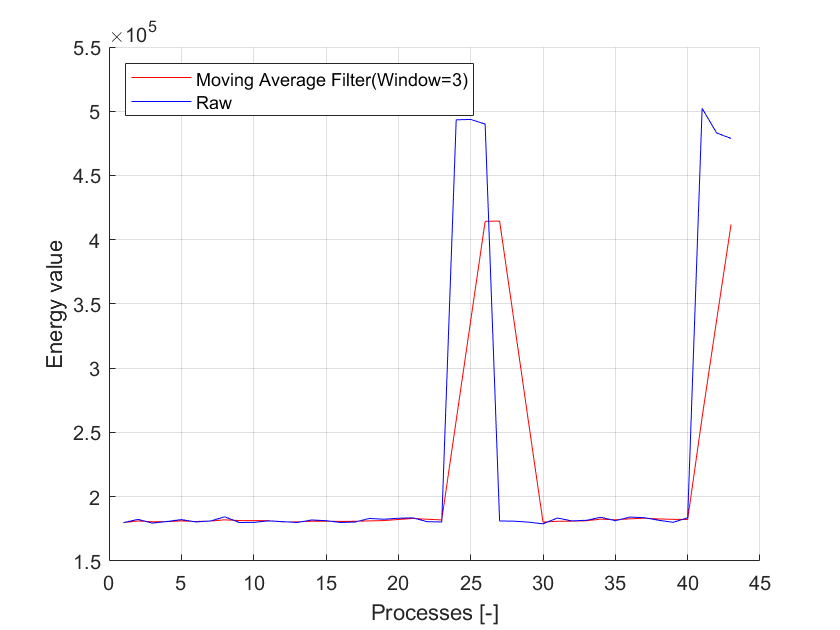

idx_rand = randi(23);
% Concatenate features (Temperature and Current)
features_in_array = [RUL_data{idx_rand,TEMP} RUL_data{idx_rand,CURRENT}];
features_in_table = array2table(features_in_array);
features_in_table.Properties.VariableNames = [strcat("temp_",names_of_feature) strcat("current_",names_of_feature)];
features_in_table_MAF5 = varfun(@(x) movmean(x, [window_size 0]), features_in_table);
features_in_table_MAF5.Properties.VariableNames = features_in_table.Properties.VariableNames;
figure; hold on; grid on;
xlabel('Processes [-]'); ylabel('Energy value');
plot(features_in_table_MAF5.temp_Energy,'r-');
plot(     features_in_table.temp_Energy,'b-');
legend('Moving Average Filter(Window=3)','Raw');
legend('Location','northwest');

Importance of features are tabulated as below. Using the table, Current's RMS and mean influences the most.

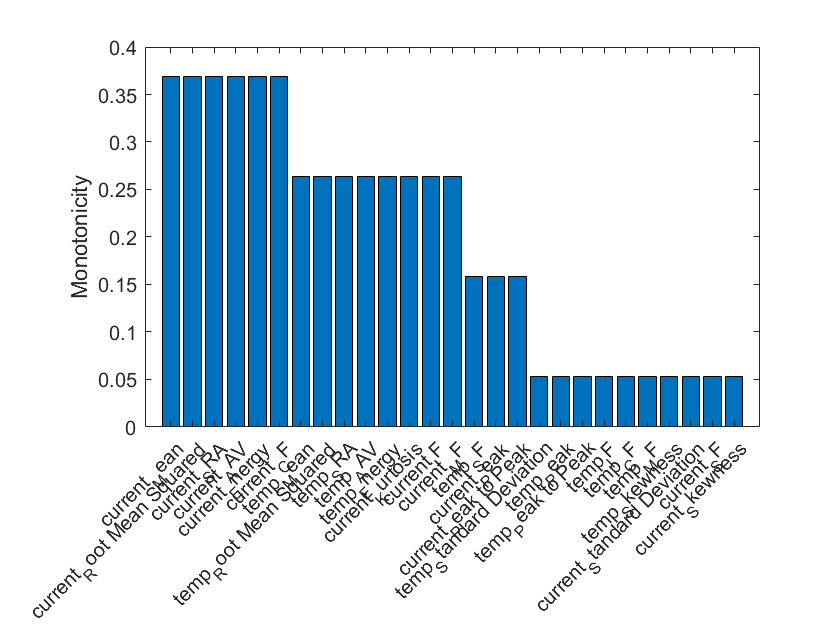

break_point = RUL_data{idx_rand,2}(3);
feature_monotonicity = monotonicity(features_in_table_MAF5(break_point:end,:), 'WindowSize', 0);
names   = string(feature_monotonicity.Properties.VariableNames);
important_feature = table2array(feature_monotonicity)   ;
helperSortedBarPlot(feature_monotonicity,'Monotonicity');

confidence_level = 0.2;
train_selected   = features_in_table_MAF5(:, feature_monotonicity{:,:}>=confidence_level);
feature_selected = features_in_table_MAF5(:, feature_monotonicity{:,:}>=confidence_level)

feature_selected = 43×14 table
    temp_Kurtosis    temp_Standard Deviation    temp_Root Mean Squared    temp_SRA    temp_AAV    temp_Skewness    current_Kurtosis    current_Standard Deviation    current_Root Mean Squared    current_SRA    current_AAV    current_Peak to Peak    current_SF    current_CF
    _____________    _______________________    ______________________    ________    ________    _____________    ________________    __________________________    _________________________    ___________    ___________    ____________________    __________    __________

       2.2209                 3.328                     70.689             70.574      70.612        -0.27926           2.2037                  0.075802                      1.6001                1.5974         1.5983               0.268             1.0011        1.0731  
       2.2715                3.3427                     70.934             70.819      70.857        -0.21522           2.6435                  0.078

mean_train = mean(train_selected{:,:});
std_train  = std(train_selected{:,:});
train_norm = (train_selected{:,:}- mean_train)./std_train;
coeff_pca  = pca(train_norm)

coeff_pca =     0.0508    0.5279   -0.3897    0.5726   -0.4714   -0.0296    0.1178    0.0356   -0.0253    0.0089   -0.0000    0.0000   -0.0000    0.0000
    0.3080   -0.0072   -0.1412   -0.1077    0.0045    0.8175    0.2403   -0.0988    0.2399    0.2831   -0.0019   -0.0042    0.0002    0.0001
    0.3050   -0.1216   -0.0411    0.1405    0.1076    0.0078   -0.0960    0.0961   -0.3922    0.1337    0.3419    0.6800   -0.0713   -0.2908
    0.3049   -0.1222   -0.0405    0.1418    0.1080    0.0029   -0.0982    0.0968   -0.3968    0.1320   -0.2647   -0.5787   -0.0469   -0.5075
    0.3049   -0.1220   -0.0407    0.1414    0.1079    0.0046   -0.0975    0.0965   -0.3952    0.1326   -0.0756   -0.0971    0.1180    0.7982
   -0.0180    0.5498   -0.4011   -0.1795    0.6594   -0.0147   -0.2601   -0.0295    0.0255   -0.0140    0.0000    0.0000    0.0000    0.0000
    0.1279    0.4204    0.7624    0.2480    0.0499    0.1637   -0.3316   -0.1343    0.0619    0.0547    0.0000   -0.0000   -0.0000   -0.0000
 

There is a random number generator, and random dataset is selected. 

For the 21st dataset, among 28 features, 17 features are selected using 0.15 confidence level and 14 features are selected using 0.20 confidence level.

Then, the PCA process is done afterwards to pick a health indicator.

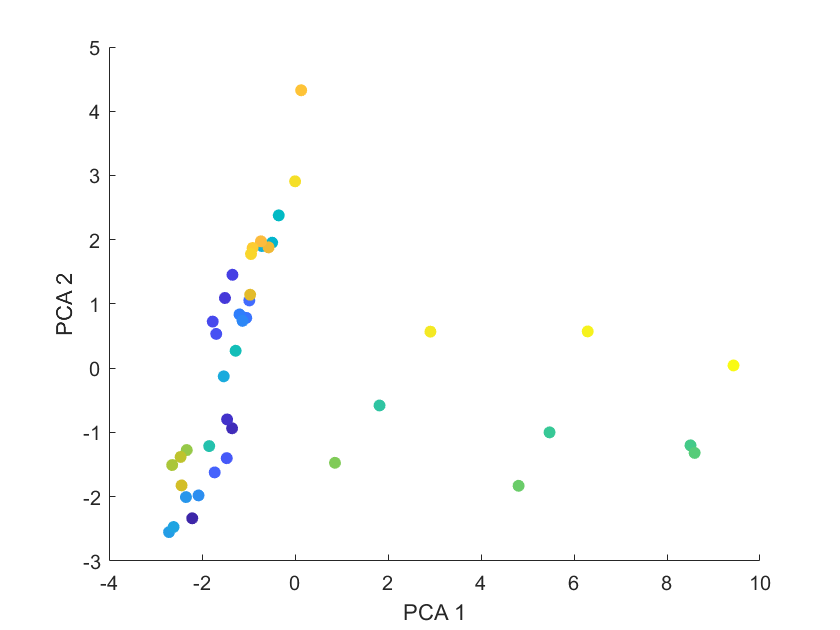

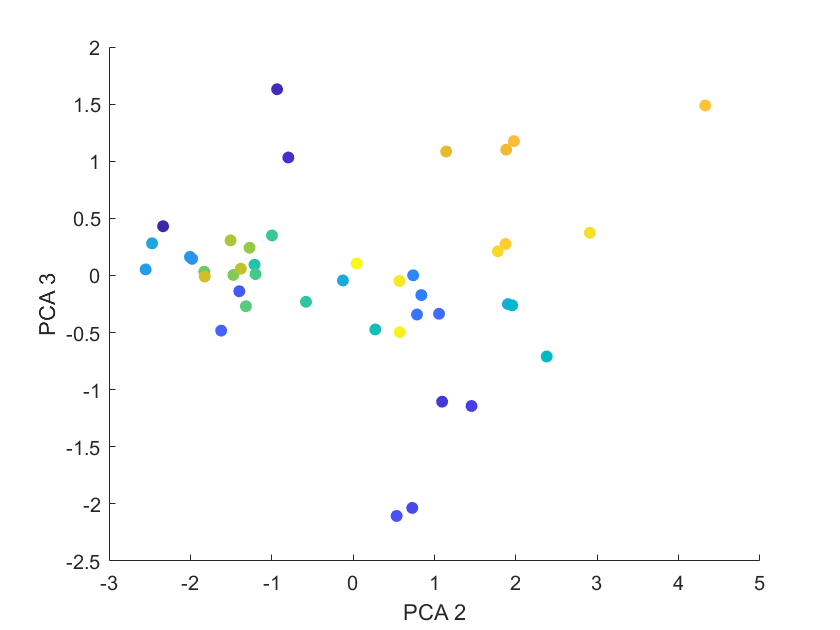

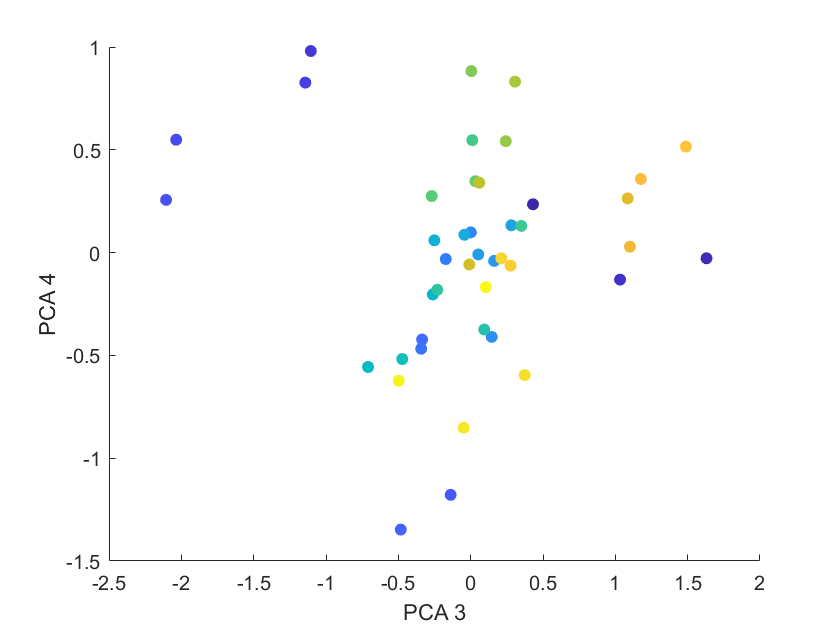

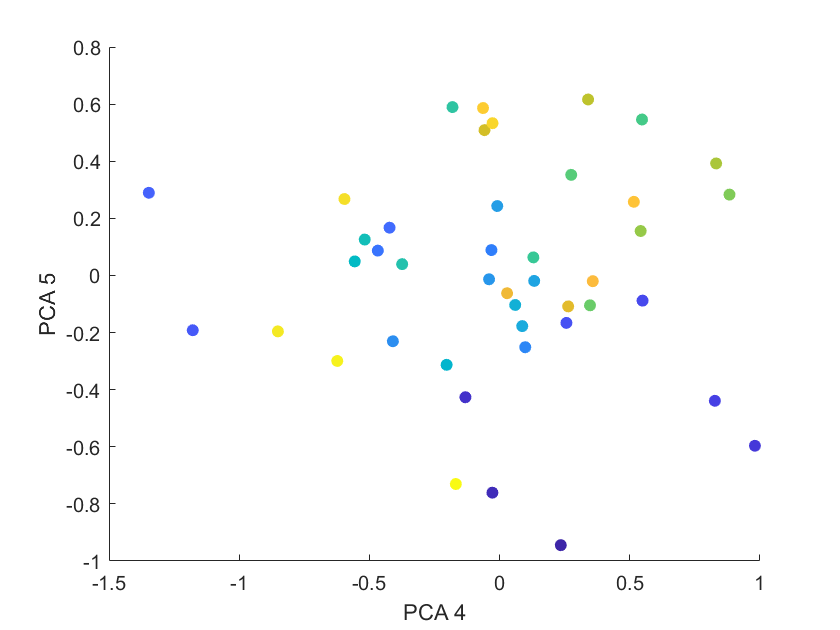

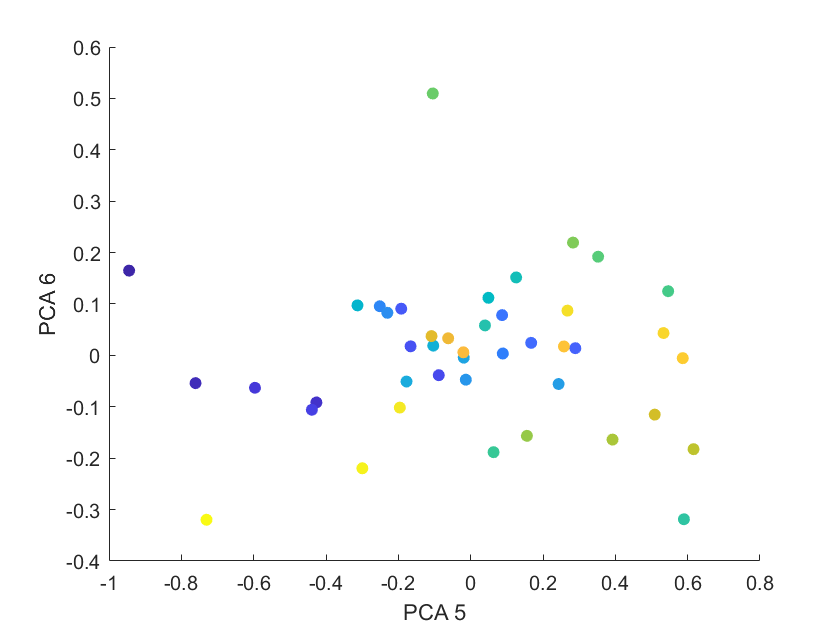

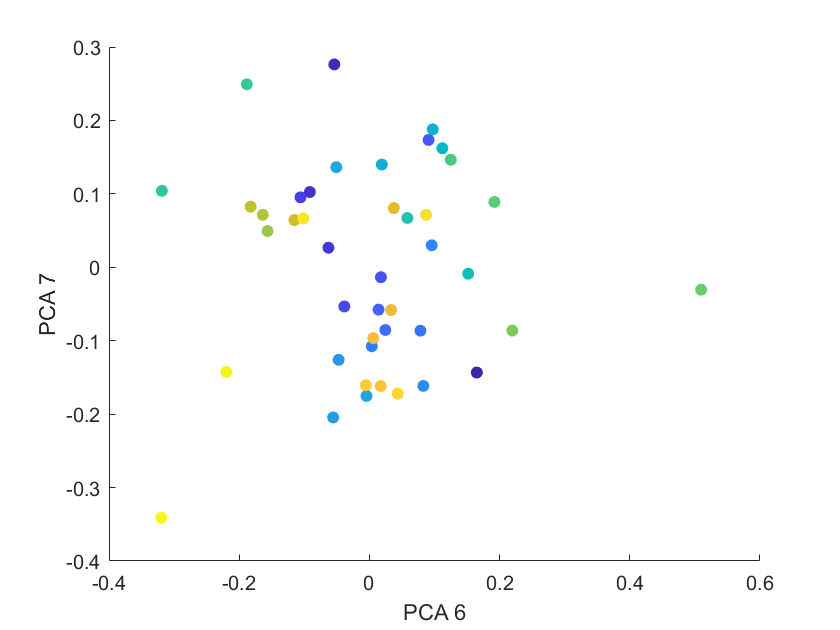

num_pca = length(coeff_pca(:,1));
for idx = 1:num_pca
    PCA(:,idx) = (feature_selected{:,:} - mean_train) ./ std_train * coeff_pca(:, idx);
end
for idx = 1:num_pca-1
    figure;
    scatter(PCA(:,idx), PCA(:,idx+1), [], 1:length(RUL_data{idx_rand,3}(:,1)), 'filled');
    xlabel(strcat("PCA ",num2str(idx)))  ;
    ylabel(strcat("PCA ",num2str(idx+1)));
    if idx >5
        break;
    end
end

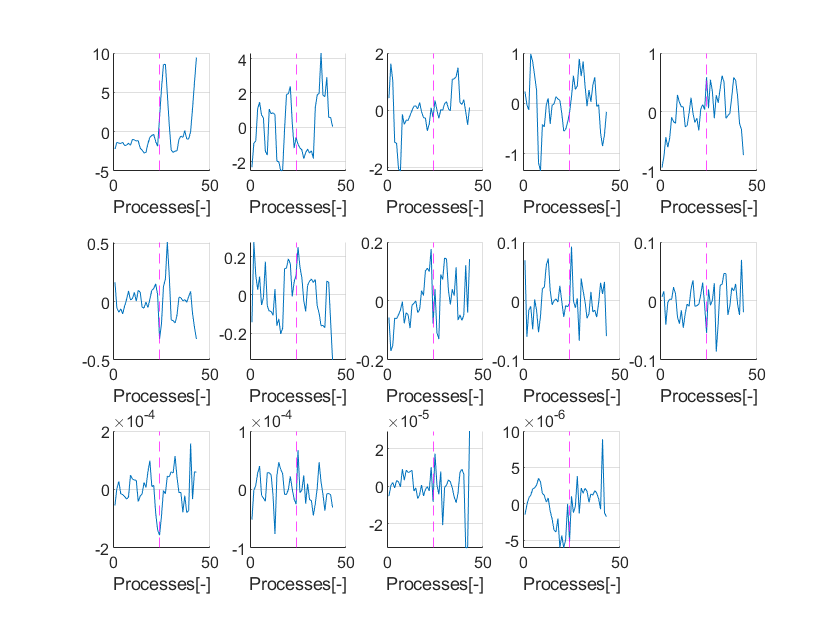

min_process = RUL_data{idx_rand,2}(3);
max_process = RUL_data{idx_rand,2}(4);

figure;
div_factor = 5;
for idx =1:num_pca
    subplot(ceil(num_pca/div_factor),div_factor,idx); 
    hold on; grid on;
    xline(min_process,'m--');
    plot(PCA(:,idx));
    xlabel('Processes[-]');
end

The graph above is PCA information and the pink line that crosses the x-axis is the break point where degradation starts.

# Fault Monitoring and Warning

By looking at the graph, PCA(1) shows the big peak at the start of the error and it tends to increase.

Therefore, the PCA(1) is chosen as a Health Indicator.

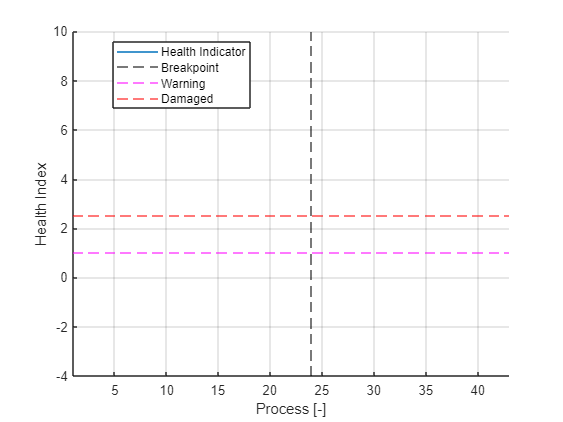

health_indicator = PCA(:,1);
processes = 1:max_process  ;
figure;  hold on; grid on  ;
plot(processes, health_indicator,'DisplayName','Health Indicator') ; 
xlabel('Process [-]'); ylabel('Health Index');xlim([1 max_process]);
xline(min_process, 'k--','DisplayName','Breakpoint');
yline(1.0,'m--','DisplayName','Warning')         ;
yline(2.5,'r--','DisplayName','Damaged')         ;
legend('Location','best')                        ;

# RUL Estimation

In this part, the Remaining Useful Life(RUL) model is built with the health indicator from features extracted and selected. The degradation model is as the following:

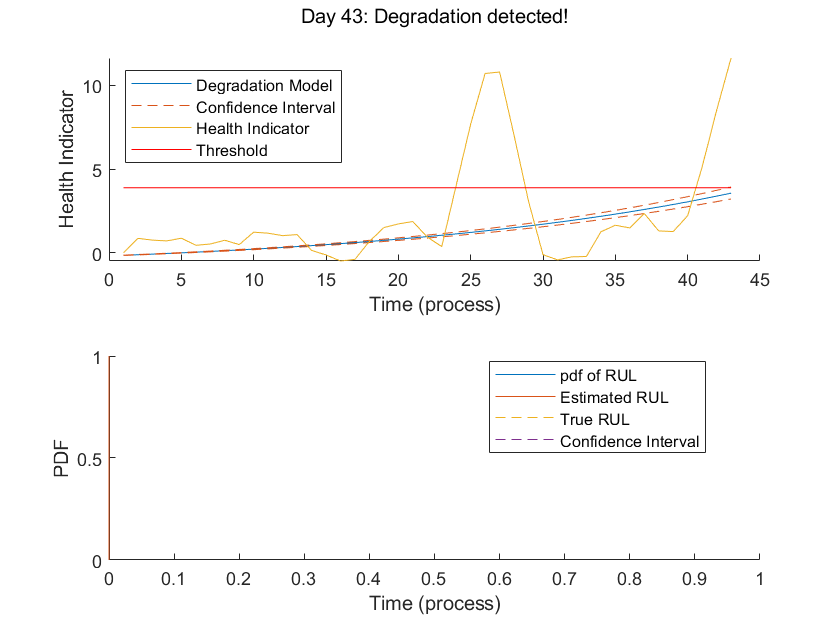

healthIndicator = health_indicator- health_indicator(1);
threshold_HI = max(healthIndicator)/3.0;
mdl = exponentialDegradationModel(...
 'Theta', 1, ...
 'ThetaVariance', 1e6, ...
 'Beta', 1, ...
 'BetaVariance', 1e6, ...
 'Phi', -1, ...
 'NoiseVariance', (0.1*threshold_HI/(threshold_HI + 1))^2, ...
 'SlopeDetectionLevel', 0.05);
N_health = length(healthIndicator);
estRULs  = zeros(N_health,1);
trueRULs = zeros(N_health,1);
CI_RULs  = zeros(N_health,2);
pdfRULs  = cell (N_health,1);
figure;
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);
timeUnit = 'process';
for current_process= 1:N_process
 update(mdl, [current_process healthIndicator(current_process)]);
 [estRUL, CIRUL, pdfRUL] = predictRUL(mdl, ...
                            [current_process healthIndicator(current_process)], ...
                             threshold_HI);
 trueRUL = N_health- current_process + 1;
 helperPlotTrend(ax1, current_process, healthIndicator, mdl, threshold_HI, timeUnit);
 helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
 estRULs(current_process) = estRUL;
 trueRULs(current_process) = trueRUL;
 CIRULs(current_process, :) = CIRUL;
 pdfRULs{current_process} = pdfRUL;
 pause(0.1);
 legend('Location','best')
end

To validate the degradation model, $\alpha$-$\lambda$ plot is drawn as below. This shows boundaries and overlapped area of the prediction of degradation model and the true RUL. 

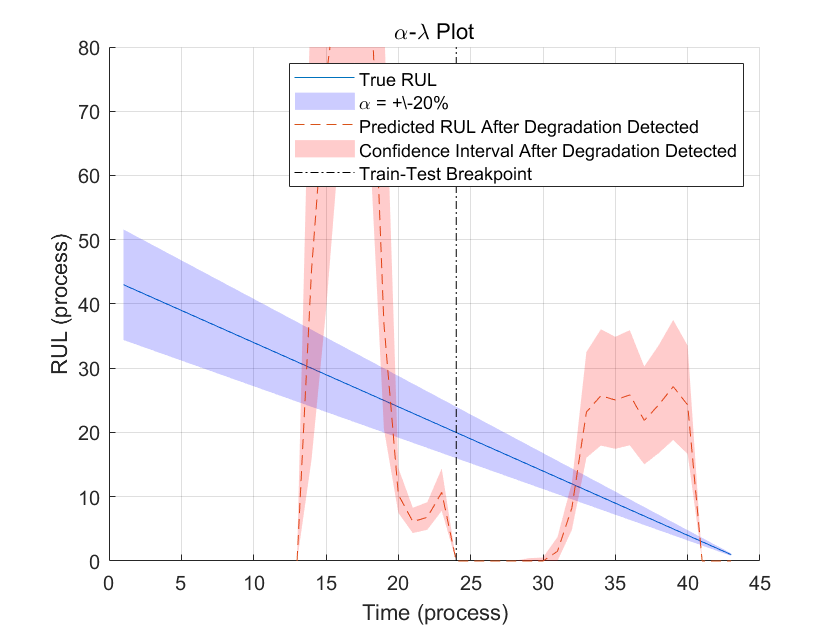

alpha = 0.2;
detectTime = mdl.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, trueRULs, estRULs, CIRULs, ...
 pdfRULs, detectTime, break_point, timeUnit);
title('\alpha-\lambda Plot')      

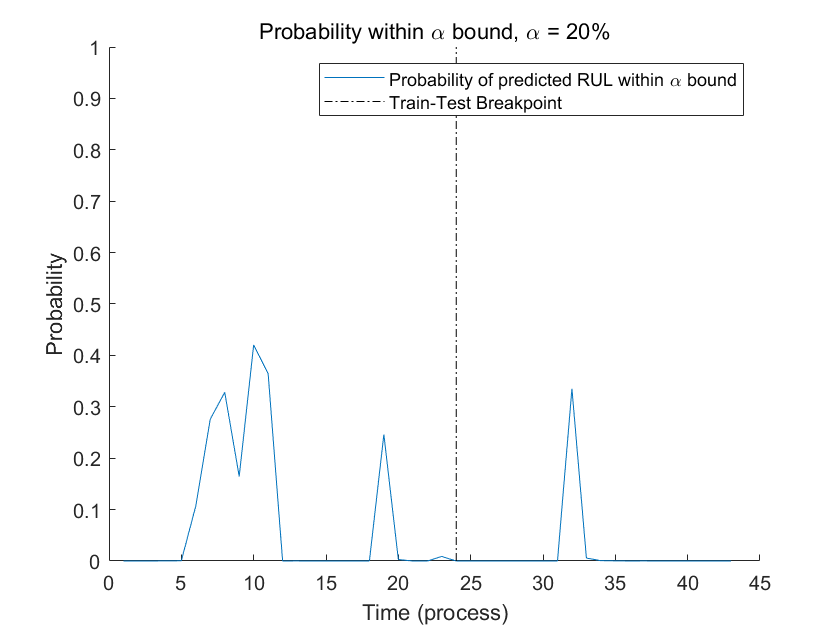

figure
t = 1:N_process;
hold on
plot(t, prob)
plot([break_point break_point], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])

The peak probability after train-test breakpoint is 0.3(30%) which does not meet the project criteria.

# Discussion

- The difficult part of predicting RUL using ML is that the feature tends to increase very rapidly without any degradation signs. To achieve the goal, the signals should be collected in more frequent manner so that the features can be extracted more frequently.

- Classification models SVM, Tree, KNN showed weak performance on the dataset. Reason for this is that the models are weak learners. SVM, Tree, KNN are basic and simple machine learning methods and are prone to overfit/underfit. On the other hand, random tree is a group of trees with bagging method and showed the best performance among the classification models tried in the project.

# Conclusion

    In the project, classification of error using machine learning has achieved the specific goal from the proposal(90% F1-Score on classification). This is achieved using Random Forest model with 20 trees as a hyperparameter. Random forest model is a hybrid method. More specifically, bagging algorithm is used. Underfitting and overfitting occurs with a learning process for the dataset as there is small number of labels to train or test. Random forest model ensures stability and accuracy using multiple tree models as its baseline. Graph below[4]  shows the most widely used algorithm in 50 recent papers, Random Forest shows the biggest contribution. 

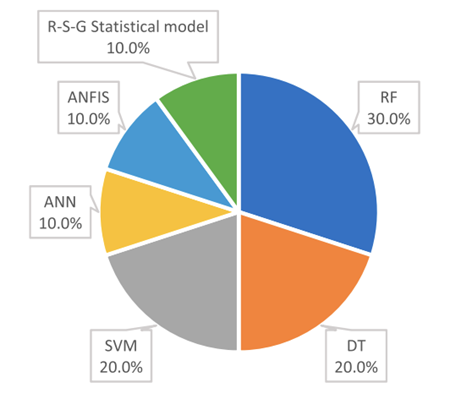

# Paper Review

In the [5][paper](https://ieeexplore.ieee.org/document/9416802), which is published in 2021, introduces Twin SVM and adaptive thresholding. 

Background of the research

1) Reduce the cost of O&M in wind turbine system, condition monitoring is important.

2) Wind turbine shows error in the bearings(Rotary machine fault)

    A condition monitoring (CM) system generally tracks the temporal behavior of variables in time-series such as wind speed, gearbox temperature, generator bearing temperature, nacelle temperature, and ambient temperature.

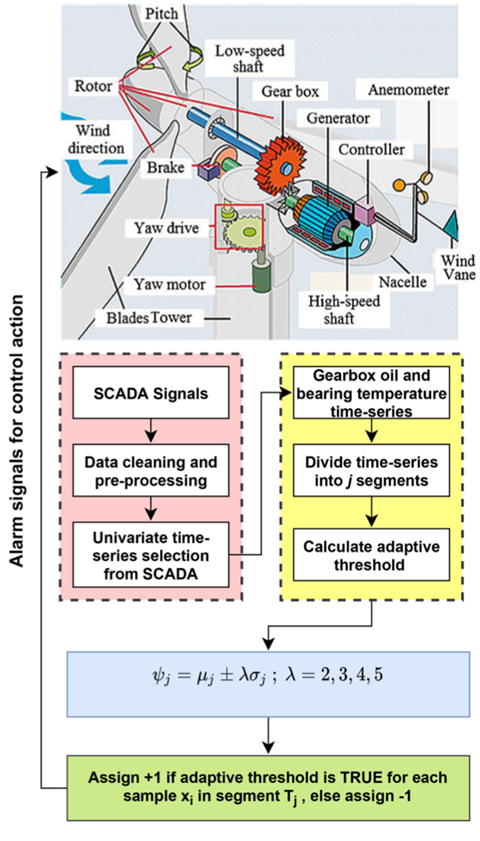

**Techniques used in the paper**

**Adaptive Thresholding**

- Univariate time-series segmentation for analyzing the physical system’s temporal behavior.

**Twin SVM**

- Two hyperplanes that satisfies each equations (Optimality Condition Problem $\rightarrow$ KKT, Chebyshev’s inequality and Wolfe duality problem)

**Result of Twin SVM with/without Adaptive Threshold**

By using Adaptive Thresholding and Twin SVM method, the paper improved time-efficiency and accuracy for real-time approach

**Functions**

function xfeature = get_features(x)
% This is based on the function timeFeatures() 
% Input : Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);

p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;
xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));
end
function xfeature = get_features_sound(x)
% This is based on the function timeFeatures() 
% Input : Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
xfeature.mean     =mean(x);
xfeature.std      =std(x);
xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);


xfeature.mean  = xfeature.mean  (1);
xfeature.std   = xfeature.std   (1);
xfeature.rms   = xfeature.rms   (1);
xfeature.sra   = xfeature.sra   (1);
xfeature.aav   = xfeature.aav   (1);
xfeature.energy= xfeature.energy(1);
xfeature.peak  = xfeature.peak  (1);
xfeature.ppv   = xfeature.ppv   (1);
xfeature.if    = xfeature.if    (1);
xfeature.sf    = xfeature.sf    (1);
xfeature.cf    = xfeature.cf    (1);
xfeature.mf    = xfeature.mf    (1);
xfeature.sk    = xfeature.sk    (1);
xfeature.kt    = xfeature.kt    (1);
end

function xfeature = get_features_temperature(x,y)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
N_Y= length(y);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);

p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;
xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));

xfeature.error = sum(y)/N_Y;
end

%%
function average_feature = get_average_feature(x,feature_name)
% Input: the whole cell
    FEATURES =3;
    N = length(x);
    feature = 0.0;
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        feature = feature + val(1);
    end
    average_feature = feature/N;
end

%%
function vectors = get_all_feature(x,feature_name)
% Input : whole cell
% Output: Array type
    FEATURES =3;
    N = length(x);
    vectors = [];
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        vectors = [vectors; val(1)]; 
    end
end

%%
function [frequency , Amplitude] = get_fft(data,Fs)
% Input : data: Time-series data
%         Fs  : Sampling Frequency
% Output: frequency: Frequency Domain(Bound)
%         Amplitude: Corresponding amplitude of fft data to the frequency
    N = length(data);
    frequency = 0.0:Fs/N:Fs/2;
    fft_data = abs(fft(data)/N);
    fft_data = fft_data(1:floor(N/2)+1);
    fft_data(2:end-1) = 2*fft_data(2:end-1);
    Amplitude = fft_data;
end

%%
function frequency_features = get_freq_features(fft_data, Fs)
% Input  fft_data: fft amplitude data
%        Fs: sampling frequency
% Output frequency_features: table for frequency features. 
    N = length(fft_data);
    frequency_features = table;
    frequency_features.max_amplitude     = max(fft_data);
    frequency_features.frequency_of_max_amplitude = (find(fft_data == max(fft_data))-1)*Fs/N;
    frequency_features.DC_value = fft_data(1);
end
function xfeature = get_features_plc(x_t,x_c,y)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x_t);
N_Y= length(y);

xfeature.tem_mean     =mean(x_t);
xfeature.tem_std      =std(x_t);
xfeature.tem_rms      =sqrt(sum(x_t.^2)/N);
xfeature.tem_sra      =(sum(sqrt(abs(x_t)))/N).^2;
xfeature.tem_aav      =sum(abs(x_t))/N;
xfeature.tem_energy   =sum(x_t.^2);
xfeature.tem_peak     =max(x_t);
xfeature.tem_ppv      =peak2peak(x_t);
xfeature.tem_if       =xfeature.tem_peak/xfeature.tem_aav;
xfeature.tem_sf       =xfeature.tem_rms/xfeature.tem_aav;
xfeature.tem_cf       =xfeature.tem_peak/xfeature.tem_rms;
xfeature.tem_mf       =xfeature.tem_peak/xfeature.tem_sra;
xfeature.tem_sk       =skewness(x_t);
xfeature.tem_kt       =kurtosis(x_t);

xfeature.cur_mean     =mean(x_c);
xfeature.cur_std      =std(x_c);
xfeature.cur_rms      =sqrt(sum(x_c.^2)/N);
xfeature.cur_sra      =(sum(sqrt(abs(x_c)))/N).^2;
xfeature.cur_aav      =sum(abs(x_c))/N;
xfeature.cur_energy   =sum(x_c.^2);
xfeature.cur_peak     =max(x_c);
xfeature.cur_ppv      =peak2peak(x_c);
xfeature.cur_if       =xfeature.cur_peak/xfeature.cur_aav;
xfeature.cur_sf       =xfeature.cur_rms/xfeature.cur_aav;
xfeature.cur_cf       =xfeature.cur_peak/xfeature.cur_rms;
xfeature.cur_mf       =xfeature.cur_peak/xfeature.cur_sra;
xfeature.cur_sk       =skewness(x_c);
xfeature.cur_kt       =kurtosis(x_c);

% p1 = fft(x);
% p1(2:end-1)= 2.0 * p1(2:end-1); 
% xfeature.fft = p1;
% xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));

xfeature.error = sum(y)/N_Y;
end

## Reference

[1] (주) KEMP, *Innozinc**세라믹 아연도금**,* [http://kempkorea.com/](http://kempkorea.com/) 

[2] Rauber, Thomas W., Francisco de Assis Boldt, and Flavio Miguel Varejao. "Heterogeneous feature models and feature selection applied to bearing fault diagnosis." *IEEE Transactions on Industrial Electronics* 62.1 (2014): 637-646.

[3] Toliyat, Hamid A., et al. *Electric machines: modeling, condition monitoring, and fault diagnosis*. CRC press, 2017.

[4] Polverino, Lorenzo, et al. "Machine learning for prognostics and health management of industrial mechanical systems and equipment: A systematic literature review." *International Journal of Engineering Business Management* 15 (2023): 18479790231186848

[5] Dhiman, H. S., Deb, D., Muyeen, S. M., & Kamwa, I. (2021). Wind turbine gearbox anomaly detection based on adaptive threshold and twin support vector machines. *IEEE Transactions on Energy Conversion*, *36*(4), 3462-3469.